# The Astounding Salemi Stats

The report examines three new baseball stats that will revolutionize baseball analysis.  There are three Salemi Stats:

**BasesPerHit (BPH)**

We divide the total bases by the number of hits to get the average number of bases we get from every hit. 


$$\frac{\left(H+2B+2*3B+3*\mathrm{HR}\right)}{H}$$


**Productive Strikouts (PSO)**


$$\mathrm{mynewstats}=\frac{\mathrm{AB}}{{\mathrm{HOTDOGS}}^5 }$$


Calculate the hits, walks, and hit by pitches  per strikeout.


$$\frac{\left(H+\textrm{BB}+\textrm{HBP}\right)}{\textrm{SO}}$$


**Speed Trial (ST)**

We calculate the stolen bases - 2 * caught stealing per H


$$\frac{\left(\textrm{SB}-2*\textrm{CS}\right)}{H}$$


## Read the data

data = readtable("batting.csv");

Remove the team names

data = removevars(data, "Tm");

## Create the statistics

#### BPH

*Code hidden*

data.TB = (data.H + data.x2B + 2 * data.x3B + 3 * data.HR );
data.BPH = data.TB ./ data.H;

#### PSO

*Code hidden*

data.PSO = (data.H + data.BB + data.HBP) ./ data.SO;

#### ST

*Code hidden*

data.ST = (data.SB - 2*data.CS) ./ data.H;
data(1:5, [4 20 21 22])

ans = 5x4 table
     R      BPH       PSO         ST   
    ___    ______    ______    ________

    807    1.6533    1.4277    0.047177
    772    1.6423    1.4534    0.041754
    641    1.6139    1.2198     0.03211
    662     1.525    1.6681    0.057288
    661    1.6176    1.2553    0.030186


## Find the best statistic

We'll use the plot matrix to see the greatness of the new stats and then calculate the coefficients.

### Plot Matrix

First we look at a plot matrix using the four columns in the matrix above.

*Code hidden*

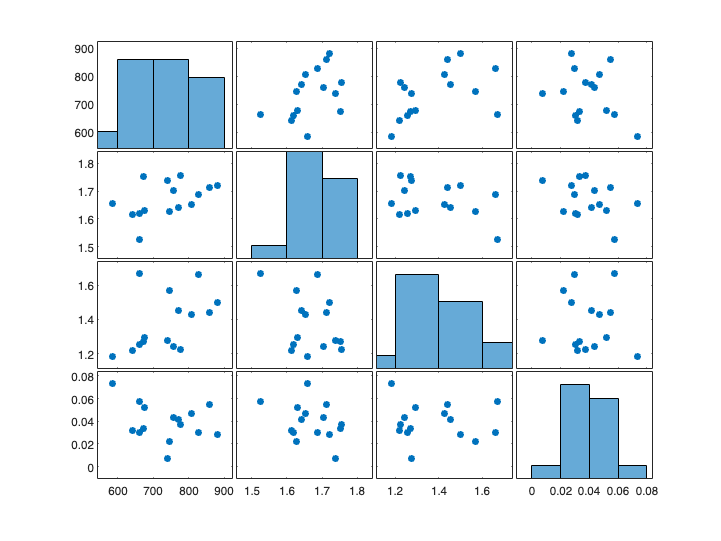

plotmatrix(data{:,[4 20 21 22]})

Hmm . . . this is not looking so good.

### Correlation Coefficients

Now calculate the Correlation Coeffiicients with the order R BPH PSO ST.

*Code hidden*

corrcoef(data{:,[4 20 21 22]})

ans =     1.0000    0.4646    0.4703   -0.2927
    0.4646    1.0000   -0.3567   -0.3445
    0.4703   -0.3567    1.0000   -0.0657
   -0.2927   -0.3445   -0.0657    1.0000


## Conclusion

My new statistics are all terrible!  Far worse than batting average.

The best of the worst was Productive Strike Outs (PSO)


$$\frac{\left(H+\textrm{BB}+\textrm{HBP}\right)}{\textrm{SO}}$$


This statistic had a .4703 correlation to Runs Scored (R).